# Control y Programación de Robots (GIERM)

## Práctica 2, Ejer1: Localización basada en LSE

## Código para Alumnos

This program implements a Least Square Error (LSE) Localization (only positioning)  in a Map with N Landmarks. The robot is equipped with a range-only sensor which measures the distance to all the landmarks in the map. The optimization starts from the robot odometry which is randomly generated from the True Pose.

Javier Monroy & Cipriano Galindo, Oct. 2022

clc;
clear all; 
close all;
addpath(['auxmatlab/aux_functions'], 'auxmatlab/aux_functions_prob', 'p01lab01');

## PARAMETERS

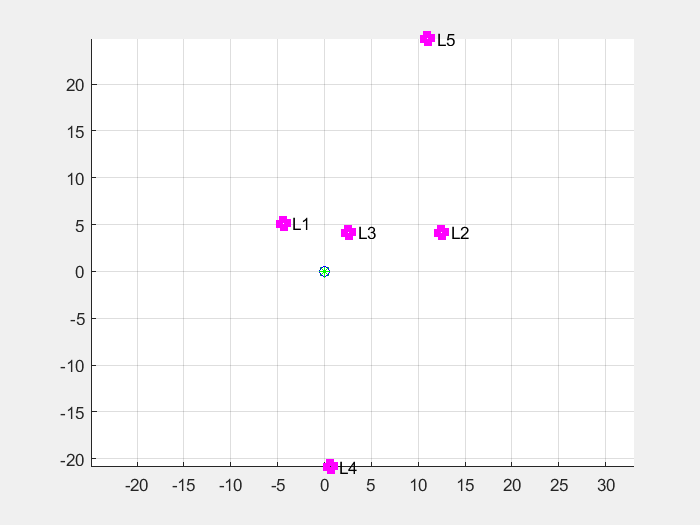


% 1 Crea un mapa con la ubicación aleatoria (posición en plano X,Y) de 5 landmarks
% 2 Establece la varianza de las distancias var_d y crea la matriz R
% 3 Define la matriz U de covarianzas (medio metro y medio grado)
% 4 Inicializa el estado de z, h, xTrue, xEst, xOdom y jH
% 5 Establece parámetros para el bucle interno LSE - Gauss-Newton
% 6 Dibuja los landmarks y la posición inicial del robot

% 1 Map
nLandmarks = 5;
mapSize = 50;                               % Lengh in meters
Map = mapSize*rand(2,nLandmarks)-mapSize/2; % Landmarks uniformly distributed in map

% 2 Noise in measurements
var_d = 0.05^2;                      % variance of the range measurement [noise per meter]
R = zeros(nLandmarks,nLandmarks);   % covariance matrix of the landmarks observations (noise depends on distance)

% 3 Control Action (square) & noise in robot movement
inc_x = 1;                  % the robot moves 1 m. at each step, but affected by noise
inc_phi = pi/2;             % the robot turns 90 deg at certain points
u_stdx = 0.5;
u_stdy = 0.5;
u_stdphi = 0.5*pi/180;
U = diag([u_stdx,u_stdy,u_stdphi]).^2;  % covariance of the odometry noise

% 4 System state definition
z = zeros(nLandmarks,1);    % observations to all landmarks
h = zeros(nLandmarks,1);    % predicted observations (sensor model)
xTrue = zeros(3,1);         % Simulated true pose of the robot (in this case xOdom affected by noise)
xEst = zeros(3,1);          % pose estimated by the LSE method
xOdom = zeros(3,1);         % position given by odometry (noise free)
jH = zeros(nLandmarks,2);   % jacobian of the observation function for all the landmarks
                            % jH has 2 columns because we only consider
                            % (x,y), not orientation

% 5 Parameters for the Gauss-Newton optimization loop (iterative)
nIteration = 100;
tolerance = 1.0e-09;  

% 6 Initial Graphics
figure(1);
set(gcf,'Visible','on');    % pup-up window
hold on; 
grid on; 
axis equal;
% plot landmarks (magenta squares)
plot(Map(1,:),Map(2,:),'sm','LineWidth',4);
% Plot Labels
for k = 1:size(Map,2)
    text( Map(1,k)+1,Map(2,k), sprintf('L%d',k) );
end
% plot robot positions (no orientation)
plot(xTrue(1),xTrue(2),'bo');   % Ground Truth (with Noise and the one we want to estimate)
plot(xOdom(1),xOdom(2),'r.');   % Odometry or ideal (Noise-free)
plot(xEst(1),xEst(2),'g*');     % the last estimation using LSE is plot in green

## MAIN LOOP

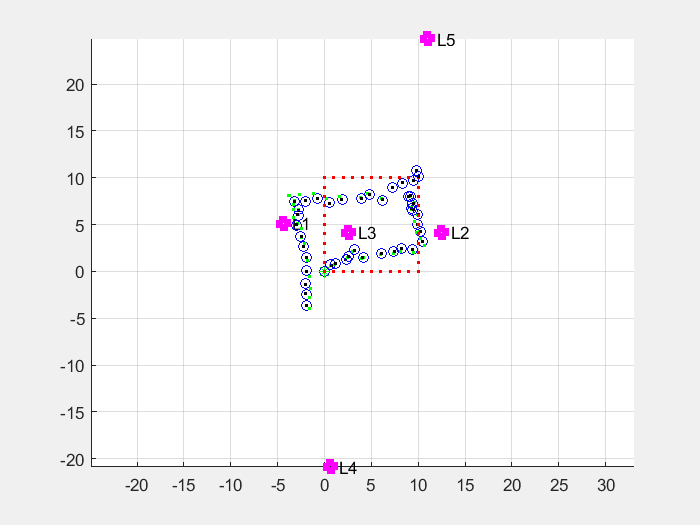

% 7 Inicializa el bucle externo iter/num_loops (44 movimientos) y errores
% 8 Para cada movimiento
%   9 Generar acción de control
%   10 Actualizar la odometría
%   11 Generar acción con ruido para simular comportamiento real
%   12 Actualizar la ground truth
%   13 Dibujar la posición odométrica y real del robot
%   14 Calcular z = distancia real a cada lanmark con ruido añadido
%   15 Inicializar xEst con posición de odometría
%   16 Para cada iteración de LSE
%       17 Calcular la distancia h y el jacobiano jH entre xEst y cada lanmark
%       18 Añadir R ruido dependiente z y calcular error=z-h
%       19 Calcular incremento de posición con la fórmula
%       20 Actualizar estimación de posición y graficarla


% 7
iter = 1;
num_loops = 44;    % number of times to execute the movement action
% initialization of the error vectors
loc_error = zeros(num_loops,1);
odo_error = zeros(num_loops,1);

% 8 Para cada movimiento
while iter < num_loops
    
    % 9 Generate Action (TO BE COMPLETED)
    if (mod(iter, 11)==0)
        u=[0, 0, inc_phi]';
    else
        u=[inc_x, 0, 0]';
    end

    % 10 Update xOdom: where the robot thinks it is (TO BE COMPLETED)
    xOdom = pose_comp(xOdom, u);
    
    % 11 Generate Noise sample & Noisy Action (TO BE COMPLETED)
    Sigma = diag([u_stdx,u_stdy,u_stdphi]);
    noise = Sigma*randn(3,1);
    uNoisy = pose_comp(u, noise);

    % 12 Update xTrue: This is the actual, unknown position of the robot (TO BE COMPLETED)
    xTrue = pose_comp(xTrue, uNoisy);
        
    % 13 Plot robot positions (without orientation)
    plot(xTrue(1),xTrue(2),'bo');   % Real Position (Ground Truth with Noise)
    plot(xOdom(1),xOdom(2),'r.');   % Odometry or ideal (Noise-free)
  
    % 14 SENSOR: Get an observation to all the landmarks
    % The sensor is onboard the robot, so measurements are always taken from xTrue
    for kk = 1: nLandmarks
        Delta = Map(:,kk)-xTrue(1:2);                   % true distance in the map
        z(kk) = norm(Delta) + (sqrt(var_d)*randn(1,1)); % observation (distance) afected by Gaussian noise
    end
    
    %-------------------------------
    % 15 LSE - Least Square Estimation
    %-------------------------------
    iteration = 0;
    incr = ones(1,2);       % initialize increment (step)    
    xEst = xOdom;           % initial estimation is xOdom - the odometry position (noise-free)
        
    % 16 LSE LOOP (iterative Method)
    while norm(incr)>tolerance && iteration<nIteration
        % 17 compute the prediction (from current xEst) and build the Jacobian
        for kk = 1:nLandmarks
            Delta = Map(1:2,kk)-xEst(1:2);  % Expected distances between the map and the pose estimated
            h(kk) = norm(Delta);            % predicted observation
            % Jacobian evaluated in xEst
            jH(kk,1) = -Delta(1) / h(kk);
            jH(kk,2) = -Delta(2) / h(kk);
        end
        % 18 Añadir R ruido dependiente z y calcular error=z-h
        R = diag(var_d*sqrt(z));    % observation variance grow with the root of the distance
        error = z - h;              % difference between measurement and prediction
        
        % 19 incr!
        incr = inv(jH'*inv(R)*jH) * jH'*inv(R)*error;
        
        % 20 Update Estimation xEst
        xEst(1:2) = xEst(1:2)+incr;
        iteration = iteration+1;        
        plot(xEst(1),xEst(2),'.g');     % plot current estimation (green point)
    end
        
    % LSE Estimation is Done!
    plot(xEst(1),xEst(2),'k.');     % the last estimation using LSE is plot in green
    
    % Save errors
    %--------------
    % localization error
    loc_error(iter+1) = sqrt((xTrue(1)-xEst(1))^2+(xTrue(2)-xEst(2))^2);    
    % odometry error
    odo_error(iter+1) = sqrt((xTrue(1)-xOdom(1))^2+(xTrue(2)-xOdom(2))^2);
    
    iter = iter+1;
    pause(0.1);
end 

## FINAL PLOTS

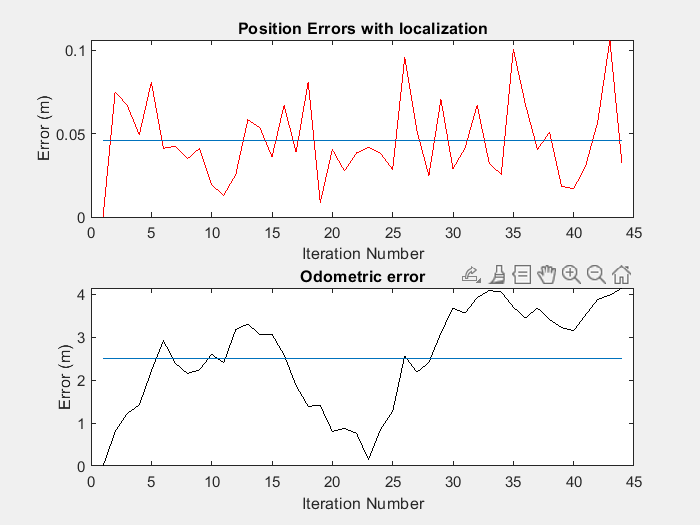

% 21 show average errors and their evolution.
avg_loc_error = mean(loc_error);
avg_odo_error = mean(odo_error);

figure(2);
set(gcf,'Visible','on');
subplot(211); 
plot(loc_error,'r'); 
hold on; 
line([1 size(loc_error,1)],[avg_loc_error avg_loc_error]); 
title('Position Errors with localization');
xlabel('Iteration Number');
ylabel('Error (m)');

subplot(212); 
plot(odo_error,'k'); 
hold on; 
line([1 size(loc_error,1)],[avg_odo_error avg_odo_error]); 
title('Odometric error');
xlabel('Iteration Number');
ylabel('Error (m)');